# EEE 321 - Signals and Systems - Lab 5 - FIR Filter

## Tuna Şahin - 22201730


$$\textrm{ID}=22201730$$


$N_1 =3,$ $N_2 =7$, $M_1 =5,M_2 =9,L=14$

##     Question 1:

Since, length of the impulse response will be the same as L, we will have 13 roots and 13 poles (Poles will all be located at 0). We will place these roots accordingly, as conjugate symmetic pairs (h[n] is required to be real) along the stopband. Placing the zeros uniformly is important to ensure a flat stopband.   

Uniformly place 2 zeros around $\omega \;=0$ with equal intervals for a flat stopband. Leave a small gap between the zeros and the passband so we do not supress it.

We will place our zeros at the following values: $\omega_1 =\frac{\pi }{30},\;\;\omega_2 =-\frac{\pi }{30}$.

boundary1 = 200;
%zeros1 = [cos(linspace(-pi/20,pi/20,2))+1j*sin(linspace(-pi/20,pi/20,2))];  %the interval is symmetric around x axis so zeros are conjugate symmetric
%zeros1 = [cos(linspace(-pi/25,pi/25,2))+1j*sin(linspace(-pi/25,pi/25,2))];
zeros1 = [cos(linspace(-pi/boundary1,pi/boundary1,2))+1j*sin(linspace(-pi/boundary1,pi/boundary1,2))];
%zeros1 = [cos(linspace(-pi/35,pi/35,2))+1j*sin(linspace(-pi/35,pi/35,2))];
%zeros1 = [cos(linspace(-pi/30,pi/30,2))+1j*sin(linspace(-pi/30,pi/30,2))];

Uniformly place 11 zeros between $\omega =\frac{\;\pi \;}{3\ldotp 5}\textrm{and}\;\omega =\frac{6\;\pi \;}{3\ldotp 5}$ with equal intervals for a flat stopband.


$$\omega_3 =\frac{\pi }{3\ldotp 5},\omega_4 =\frac{1\ldotp 625\pi }{3\ldotp 5},\omega_5 =\frac{2\ldotp 25\pi }{3\ldotp 5},\omega_6 =\frac{2\ldotp 875\pi }{3\ldotp 5},\omega_7 =\pi ,\omega_8 =\frac{4\ldotp 125\pi }{3\ldotp 5},\omega_9 =\frac{4\ldotp 75\pi }{3\ldotp 5},\omega_{10} =\frac{5\ldotp 375\pi }{3\ldotp 5},\omega_{11} =\frac{6\pi }{3\ldotp 5}$$


boundary2 = 3.6;
%zeros2 = [cos(linspace(pi/3.5,6*pi/3.5,11))+1j*sin(linspace(pi/3.5,6*pi/3.5,11))];   %the interval is symmetric around x axis so zeros are conjugate symmetric
%zeros2 = [cos(linspace(pi/3.25,5.5*pi/3.25,11))+1j*sin(linspace(pi/3.25,5.5*pi/3.25,11))];
zeros2 = [cos(linspace(pi/boundary2,2*pi-pi/boundary2,11))+1j*sin(linspace(pi/boundary2,2*pi-pi/boundary2,11))];

Plot these zeros and poles:

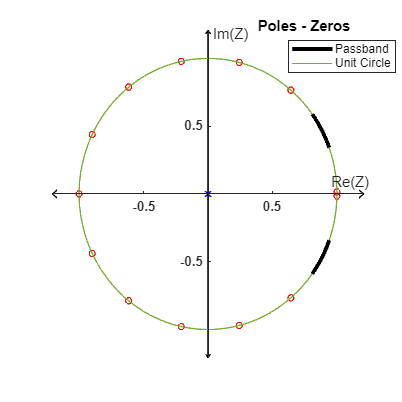

poles = [0 0 0 0 0 0 0 0 0 0 0 0 0]; %13 poles at the origin
zerosT = [zeros1 zeros2];
clf;
polezeroplot(poles,zerosT,'Poles - Zeros','Z','on',[400 400]) %function to plot poles and zeros
h = gobjects(3, 1);
h(1) = plot(cos(linspace(0,2*pi,100)),sin(linspace(0,2*pi,100)),'color',[0.4660 0.6740 0.1880],'DisplayName', 'Unit Circle'); %unit circle
h(2) = plot(cos(linspace(pi/9,pi/5,100)),sin(linspace(pi/9,pi/5,100)),'black','LineWidth',3,'DisplayName', 'Passband');   %passband positive side
h(3) = plot(cos(linspace(pi/9,pi/5,100)),sin(linspace(-pi/9,-pi/5,100)),'black','LineWidth',3,'DisplayName', 'Passband'); %passband negative side
legend(h([2 1])); %add the legend
hold off
legend("Position", [0.7171 0.8192 0.2675, 0.0812])

Each factor of the Z-domain impulse response will have the form $\frac{\;z-z_i }{z}$. We will have 13 of these factors that result in our 13 zeros.

nom = [];
for i = zerosT
    if isempty(nom)
        nom = [-i 1];
    else
        nom = conv(nom,[-i 1]); %polynomial multiplication
    end
end
n = linspace(0,13,14);

Since coefficient of $Y\left(z\right)=1$, $H\left(z\right)=X\left(z\right)$. The impulse response's values will be the same as the coefficients of $X\left(z\right)$.

disp(vertcat(real(nom),n)) %values are purely real since all factors come in conjugate pairs. Real function is used to remove +0j parts

    1.0000    0.6756    0.3251   -0.0546   -0.4112   -0.6879   -0.8390   -0.8390   -0.6879   -0.4112   -0.0546    0.3251    0.6756    1.0000
         0    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000



We do not need to calculate the Fourier Transform as we already have the $Z$ Transform. We can substitute $e^{j\omega } \;$for each $z\ldotp$

omega = linspace(0,2*pi,10000);
finalsum = zeros(1,length(omega));
for i = 1:14
    finalsum = finalsum + (nom(i)*exp(j*omega).^(-1*i));
end

Plotting the impulse response, the phase and magnitute of $H\left(e^{j\omega } \right)$. The Fourier Transform provides much more detailed information compared to the FFT of $h\left\lbrack n\right\rbrack$. It is simply there to compare and verify our results. 

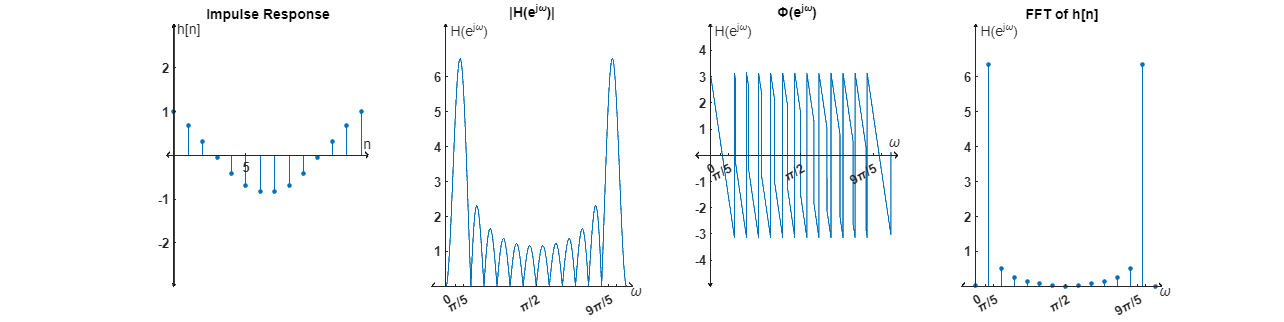

clf;
subplot(1,4,1) % impulse response
finestem(n,real(nom),'Impulse Response','n','h[n]',[-0.5 13.5],[-3 3],'off',[1600 400]) 
subplot(1,4,2) % magnitutes of FT
fineplot(omega,abs(finalsum),'|H(e^{j\omega})|','\omega','H(e^{j\omega})',[-0.5 6.5],[0 7.5],'off',[1600 400])
set(gca,'XTick',[0 pi/9 pi/5 pi 9*pi/5 17*pi/9],'XTickLabel',{0,'','\pi/5','\pi/2','9\pi/5',''})
subplot(1,4,3) % phases of FT
fineplot(omega,angle(finalsum),'\Phi(e^{j\omega})','\omega','H(e^{j\omega})',[-0.5 6.5],[-5 5],'off',[1600 400])
set(gca,'XTick',[0 pi/9 pi/5 pi 9*pi/5 17*pi/9],'XTickLabel',{0,'','\pi/5','\pi/2','9\pi/5',''})
subplot(1,4,4) % FFT of impulse response
finestem(linspace(0,2*pi,15),[abs(fft(nom,14)) 0],'FFT of h[n]','\omega','H(e^{j\omega})',[-0.5 6.5],[0 7.5],'off',[1600 400])
set(gca,'XTick',[0 pi/9 pi/5 pi 9*pi/5 17*pi/9],'XTickLabel',{0,'','\pi/5','\pi/2','9\pi/5',''})

##     Question 2:

We will now apply the chirp signal test to our filter. This signal has a varying frequency that is strictly increasing for $t>0$.  Since the function does not have a constant frequency, it does not have a constant period, hence the function is not periodic. The instantenous frequency is the derivative of the rate of change of the frequency, in this case $2\textrm{at}$.

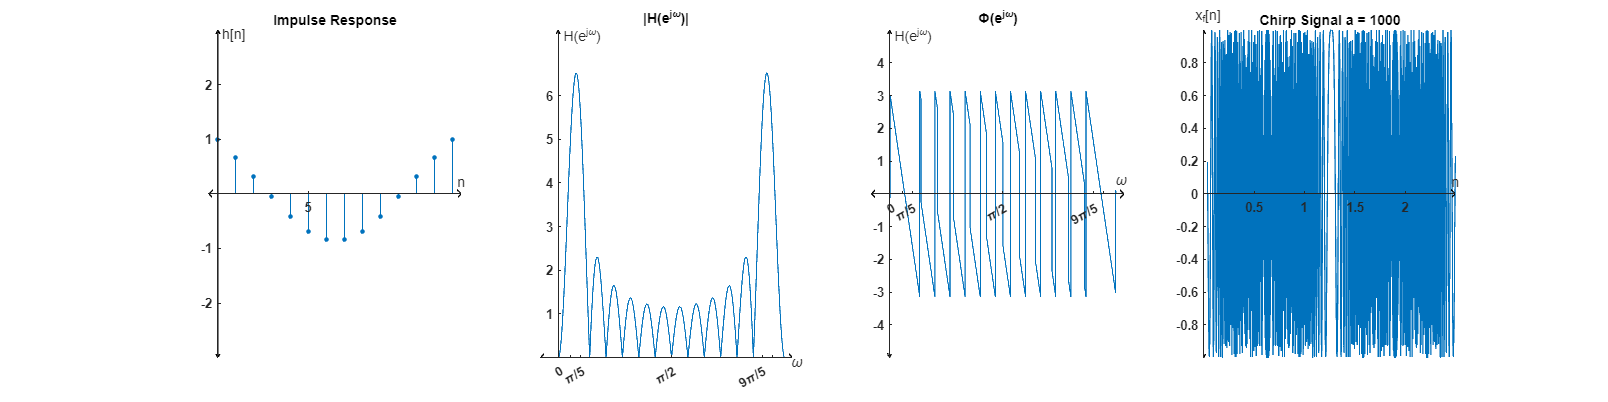

a = 1000; 
b = sqrt(pi/(a*512))*1023;
xa = cos(linspace(0,b,1024).^2*a);
filewrite(xa,'q2xa');
n = linspace(0,b,1024);
clf;
fineplot(n,xa,'Chirp Signal a = 1000','n','x_f[n]',[0 2.5],[-1 1],'off',[1600 400])

We can observe that the sampled signal is may be periodic after being sampled. We can check if the signal is periodic. If it is, it must satisfy: (using values in Q3)


$$\cos \left({a\left({\textrm{nT}}_s \right)}^2 \right)=\cos \left({a\left(\left(n+N\right)T_s \right)}^2 \right)$$



$${\textrm{an}}^2 T_s^2 +2\pi k_1 ={\textrm{an}}^2 T_s^2 +{2\textrm{anNT}}_s^2 +{\textrm{aN}}^2 T_s^2$$



$$2\pi k_1 =2\textrm{nN}\frac{\pi }{512}+N^2 \frac{\pi }{512}$$



$$k_1 =\frac{2\textrm{nN}+N^2 }{1024},k_1 \in \mathbb{Z},N\in \mathbb{Z},n\in \mathbb{Z}\;\;$$


$N=512$ is the smallest possible natural number to satisfy this property.

We have found the period of the sampled signal to be 512. Therefore, we can conclude that we plotted 2 periods of the signal.

Discretising the signal limits its maximum frequency. However, this was not the case with the original chirp signal in the analog case. So we can conclude that the discretised signal $x_2 \left\lbrack n\right\rbrack$ does not look like the analog signal $x\left(t\right)$

##     Question 3:

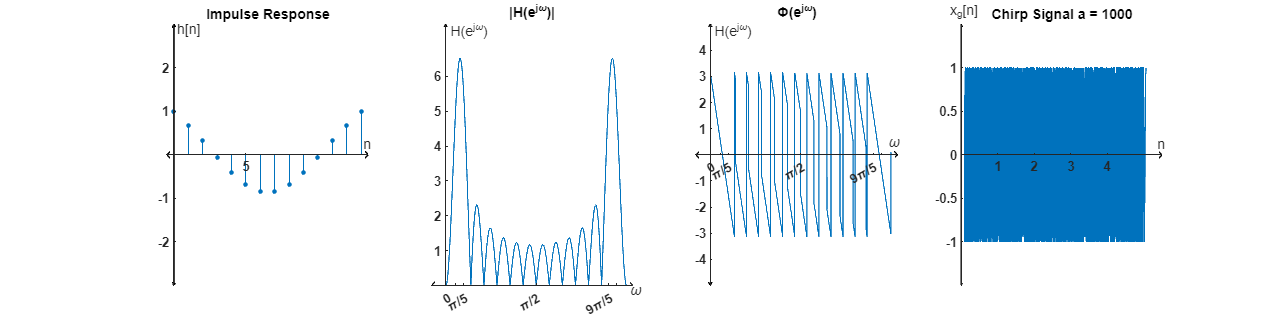

a = 1000; %given in Q3
a_length = 8192;
b = sqrt(pi/(a*8192))*(a_length-1);
n = linspace(0,b,a_length);
xa2 = cos(n.^2*a);
filewrite(xa2,'q3xa');
clf;
fineplot(n,xa2,'Chirp Signal a = 1000','n','x_g[n]',[0 5.5],[-1.5 1.5],'off',[1600 400])

We can observe that the sampled signal is may be periodic after being sampled. We can check if the signal is periodic. If it is, it must satisfy: (using values in Q3)


$$\cos \left({a\left({\textrm{nT}}_s \right)}^2 \right)=\cos \left({a\left(\left(n+N\right)T_s \right)}^2 \right)$$



$${\textrm{an}}^2 T_s^2 +2\pi k_1 ={\textrm{an}}^2 T_s^2 +{2\textrm{anNT}}_s^2 +{\textrm{aN}}^2 T_s^2$$



$$2\pi k_1 =2\textrm{nN}\frac{\pi }{8192}+N^2 \frac{\pi }{8192}$$



$$k_1 =\frac{2\textrm{nN}+N^2 }{16384},k_1 \in \mathbb{Z},N\in \mathbb{Z},n\in \mathbb{Z}\;\;$$


$N=8192$ is the smallest possible natural number to satisfy this property.

We have found the period of the sampled signal to be 8192 at the end of Q2. Therefore, we have calculated and plotted single period of this signal.

##     Question 4:

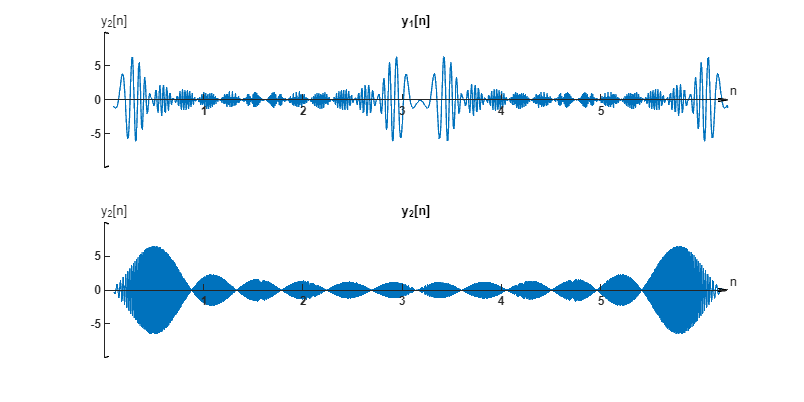

clf;
subplot(2,1,1)
temp = conv(xa,nom);
filewrite(temp,'q4y1')
n = linspace(0,length(temp)-1,length(temp))*pi/512;
fineplot(n,real(temp),'y_1[n]','n','y_2[n]',[0 6.28],[-10 10],'off',[800 400])
subplot(2,1,2)
temp2 = conv(xa2,nom);
filewrite(temp2,'q4y2')
n = linspace(0,length(temp2)-1,length(temp2))*2*pi/8192;
fineplot(n,real(temp2),'y_2[n]','n','y_2[n]',[0 6.28],[-10 10],'off',[800 400])

The frequency of the chirp signal is changing between zero the highest possible frequency with the current sampling rate. However, our filters were designed to be a bandpass filter. Therefore, only the frequencies in the passband will survive after convolution with the impulse response. We can conclude that convolution with a chirp signal can be used to identify the passband of a filter and its respective impulse response.

##     Question 5:

ya2r = fileread('q3xa');
sound = audioplayer(ya2r/max(ya2r),sqrt(pi/8192000)^-1);
while 1 
    playblocking(sound) 
end

We can observe that the frequency peaks at a certain value, then falls to 0 again. However, a continous chirp signal ($\left.x_a \left(t\right)\right)$ would have a indefinately increasing frequency. Therefore, we can conclude that these two signals are different.

##     Question 6:

y2r = fileread('q4y2');

sound2 = audioplayer(y2r,sqrt(pi/8192000)^-1); %50kHz > 48kHz
while 1 
    playblocking(sound2)
    playblocking(sound)
end

The lower frequencies (bass) has a higher amplitude compared to the higher frequencies. Also in the higher frequencies, the amplitude of the sound oscillates. This phonemona is due to the zeros located in the stopband.

##     Question 7:

Using the formula $\Omega {\;}_C =\omega {\;}_c f_c$We can realise that our passband of $\left\lbrack \frac{\pi }{9},\frac{\pi }{5}\right\rbrack$ is equivalent to [563rad/s, 1014rad/s] for the signal $y_2 \left\lbrack n\right\rbrack$.

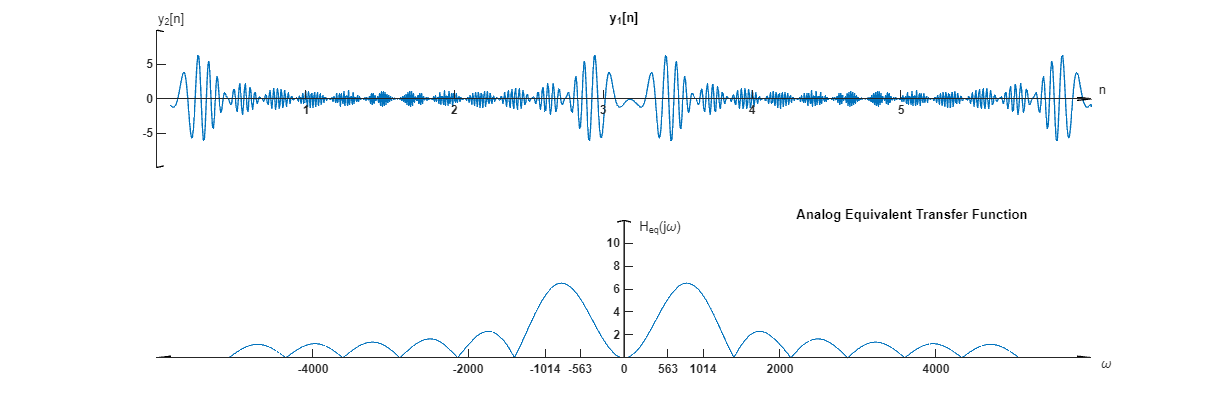

omega2 = linspace(-pi,pi,10000);
finalsum2 = zeros(1,length(omega2));
for i = 1:14
    finalsum2 = finalsum2 + (nom(i)*exp(j*omega2).^(-1*i));
end
clf;
fineplot(omega2*sqrt(8192000/pi),abs(finalsum2),'Analog Equivalent Transfer Function','\omega','H_{eq}(j\omega)',[-6000 6000],[0 12],'off',[1200 400])
set(gca,'XTick',[-4000 -2000 -1014 -563 0 563 1014 2000 4000],'XTickLabel',{-4000,-2000,-1014,-563,0,563,1014,2000,4000})

k2 = find(abs(finalsum2) == max(abs(finalsum2)));
disp(abs(finalsum2(k2)))

    6.5181



k = find(floor(omega2*sqrt(8192000/pi))==563);
disp(abs(finalsum2(k)))

    5.1577



k3 = find(floor(omega2*sqrt(8192000/pi))==1014);
disp(abs(finalsum2(k3)))

    5.4233



##     Question 8:

[xn,Fs] = audioread('yelkenler_bicilecek.mp3',[1 inf],'double');
xn = xn(3250000:3750000,1).';
yn = conv(xn,nom);
yn = yn*0.5/max(yn);
audiowrite('my_filtered_song.mp3',real(yn),Fs)
clf;
plot(1:length(yn),yn)
sound3 = audioplayer(xn,Fs);
playblocking(sound3)
sound4 = audioplayer(yn,Fs);
playblocking(sound4)

The filtered recording sound d*eep. *This is because the frequencies in the bandpass are relativly low frequencies. The surviving frequencies are the low harmonics of the sounds. There is a slight sizzling noise also present. This is due to the low but oscillatory stopbands.

##     Question 9:

[xn,Fs] = audioread('my_recording.m4a',[1 inf],'double');
yn = conv(xn(1:end,1),nom);
yn = yn*0.5/max(yn);
clf;
plot(1:length(yn),yn)
sound3 = audioplayer(xn,Fs);
audiowrite('my_filtered_recording.mp3',real(yn),Fs)
playblocking(sound3)
sound4 = audioplayer(yn,Fs);
playblocking(sound4)

The effects that were audible in the previous question are also present in this question.

# Functions

##     polezeroplot Function:

Provides a plot with the standart style of pole and zero plotting.

function polezeroplot(poles,zeros,titlename,variableName,holdstate,size)
    maxx = max(real([zeros poles]));
    minx = min(min(real(zeros),min(real(poles))));
    maxy = max(max(imag(zeros),max(imag(poles))));
    miny = min(min(imag(zeros),min(imag(poles))));
    Dx = maxx-minx;
    Dy = maxy-miny;
    dx = Dx/105;
    dy = Dy/85;
    dx = max(dx,dy);
    dy = max(dx,dy);
    hold on
    for i = poles
        plot([(real(i)-dx) (real(i)+dx)],[(imag(i)-dy) (imag(i)+dy)],'blue')
        plot([(real(i)+dx) (real(i)-dx)],[(imag(i)-dy) (imag(i)+dy)],'blue')
    end
    for i = zeros
        t = linspace(0,2*pi,20);
        zx = cos(t)*dx + real(i);
        zy = sin(t)*dy + imag(i);
        plot(zx,zy,'red')
    end
    xlimits = [min((miny-10*dy),(minx-3*dx)) max((maxx+3*dx),(maxy+10*dy))];
    ylimits = [min((miny-10*dy),(minx-3*dx)) max((maxx+3*dx),(maxy+10*dy))];
    fineplot((0),(0),titlename,strcat('Re(',variableName,')'),strcat('Im(',variableName,')'),xlimits,ylimits,holdstate,size)
end

##     fileread & filewrite Function:

Saves a given array to a txt file with the specified name. Returns the same array after reading it from the same txt file.

function filewrite(x,name)
    filename = append(name,'.txt');
    % open your file for writing
    file1 = fopen(filename,'wt');
    % write the matrix
    fprintf(file1,'%f\n',x');
    % close the file
    fclose(file1);
end

function xread = fileread(name)
    filename = append(name,'.txt');
    % open your file for reading
    file1 = fopen(filename,'r');
    % write the matrix
    xread = fscanf(file1,'%f\n');
    % close the file
    fclose(file1);
end 

##     Unit Step Function:

function un = u(n)
    if n < 0
        un = 0;
    else
        un = 1;
    end
end

##     fineplot and finestem Functions:

The stem and plot functions with other configurations to get the same style as the book:

- titlename,xaxisname,yaxisname all take string values that determine the corresponding text.

- xlimits,ylimits take 1x2 arrays that hold the limits of the plot in arbitrary order

- holdstate should take holdstate = 'off' as an input if you don't want to plot to be held any other input will not hold the plot

function fineplot(n,x,titlename,xaxisname,yaxisname,xlimits,ylimits,holdstate,size)
    %even if the limits are reverse this section corrects the order
    if ylimits(1) > ylimits(2)
        ylimits = [ylimits(2) ylimits(1)];
    end
    if xlimits(1) > xlimits(2)
        xlimits = [xlimits(2) xlimits(1)];
    end

    %these measures are necessary for positioning arrows, labels etc. 
    dx = ((xlimits(2)-xlimits(1))/65);
    dy = ((ylimits(2)-ylimits(1))/85);

    %this section is to not plot values that overlap with the arrows
    lowindex = 1;
    highindex = length(n);
    for i = n   
        if (i > xlimits(1) + dx) && (lowindex == 1)
            lowindex = find(n==i);
        end
        if (i > xlimits(2) - dx) && (highindex == 1)
            highindex = find(n==i)-1;
        end
    end
    if n(lowindex) > 0 %we allow points to be drawn at the origin
        lowindex = lowindex - 1;
    end
    
    if n(highindex) < 0 %we allow points to be drawn at the origin
        highindex = highindex + 1;
    end
    
    n = n(lowindex:highindex);
    x = x(lowindex:highindex);

    %this section is responsible for axis configuration
    plot(n,x)
    xlim(xlimits)
    ylim(ylimits)
    set(get(gca,'XLabel'),'Visible','on')
    set(gca,'XAxisLocation','origin', 'box','off')
    set(gca,'YAxisLocation','origin')
    set(get(gca, 'XAxis'), 'FontWeight', 'bold')
    set(get(gca, 'YAxis'), 'FontWeight', 'bold');
    set(get(gca,'YLabel'),'Visible','on')
    set(gca,'Layer','top')
    set(gcf,'position',[(xlimits(2)-xlimits(1))/2 , (ylimits(2)-ylimits(1))/2 , size(1) , size(2)])
    
    %deletes the ticks that overlap with arrows
    xticks('auto');
    xt = xticks;
    xticks(xt(2:length(xt)-1));
    yticks('auto');
    yt = yticks;
    yticks(yt(2:length(yt)-1));
    
    % determining the ylevel to draw the arrows on the x axis
    if ((ylimits(1) * ylimits(2)) < 0) 
        xal = 0;
    elseif ylimits(1) < 0
        xal = ylimits(2);
    else
        xal = ylimits(1);
    end

    %plotting the arrows
    hold on
    if xlimits(2) > 0
        plot([(xlimits(2)-dx) xlimits(2) (xlimits(2)-dx)],[xal+dy xal xal-dy],'k') %xaxis right arrow 
    end
    if xlimits(1) < 0
        plot([xlimits(1)+dx xlimits(1) xlimits(1)+dx],[xal+dy xal xal-dy],'k') %xaxis left arrow 
    end 
    plot([0 0],[ylimits(2) ylimits(1)],'k')% y axis
    if ylimits(2) > 0 
        plot([-dx/2 0 dx/2],[ylimits(2)-dy ylimits(2) ylimits(2)-dy],'k') %yaxis top arrow 
    end
    if ylimits(1) < 0
        plot([-dx/2 0 dx/2],[ylimits(1)+dy ylimits(1) ylimits(1)+dy],'k') %yaxis bottom arrow 
    end
    
    %repositioning title & label locations
    label_h1 = xlabel(xaxisname);
    label_h1.Position(1) = xlimits(2)+dx; % change horizontal position of xlabel.
    label_h1.Position(2) = dy; % change vertical position of xlabel.c5
    label_h2 = ylabel(yaxisname,rotation=0);
    label_h2.Position(1) = dx; % change horizontal position of ylabel.
    label_h2.Position(2) = ylimits(2)+dy; % change vertical position of ylabel.
    title(titlename);
    if ((xlimits(1) * xlimits(2)) < 0) && (xlimits(1)+xlimits(2) < ((xlimits(2)-xlimits(1))/3))
        set(get(gca,'title'),'Position', [20*dx ylimits(2)-dy]) %prevents the title from colliding with ylabel
    end

    %holds or doesnt hold
    if strcmp(holdstate,'off')
        hold off
    else 
        hold on
    end
end

function finestem(n,x,titlename,xaxisname,yaxisname,xlimits,ylimits,holdstate,size)
    %even if the limits are reverse this section corrects the order
    if ylimits(1) > ylimits(2)
        ylimits = [ylimits(2) ylimits(1)];
    end
    if xlimits(1) > xlimits(2)
        xlimits = [xlimits(2) xlimits(1)];
    end

    %these measures are necessary for positioning arrows, labels etc. 
    dx = ((xlimits(2)-xlimits(1))/65);
    dy = ((ylimits(2)-ylimits(1))/85);

    %this section is to not plot values that overlap with the arrows
    lowindex = 1;
    highindex = length(n);
    for i = n   
        if (i > xlimits(1) + dx) && (lowindex == 1)
            lowindex = find(n==i);
        end
        if (i > xlimits(2) - dx) && (highindex == 1)
            highindex = find(n==i)-1;
        end
    end
    if n(lowindex) > 0 %we allow points to be drawn at the origin
        lowindex = lowindex - 1;
    end
    
    if n(highindex) < 0 %we allow points to be drawn at the origin
        highindex = highindex + 1;
    end

    %this section is responsible for axis configuration
    stem(n,x,'filled','MarkerSize',3)
    xlim(xlimits)
    ylim(ylimits)
    set(get(gca,'XLabel'),'Visible','on')
    set(gca,'XAxisLocation','origin', 'box','off')
    set(gca,'YAxisLocation','origin')
    set(get(gca, 'XAxis'), 'FontWeight', 'bold')
    set(get(gca, 'YAxis'), 'FontWeight', 'bold');
    set(get(gca,'YLabel'),'Visible','on')
    set(gca,'Layer','top')
    set(gcf,'position',[(xlimits(2)-xlimits(1))/2 , (ylimits(2)-ylimits(1))/2 , size(1) , size(2)])
    
    %deletes the ticks that overlap with arrows
    xticks('auto');
    xt = xticks;
    xticks(xt(2:length(xt)-1));
    yticks('auto');
    yt = yticks;
    yticks(yt(2:length(yt)-1));
    
    % determining the ylevel to draw the arrows on the x axis
    if ((ylimits(1) * ylimits(2)) < 0) 
        xal = 0;
    elseif ylimits(1) < 0
        xal = ylimits(2);
    else
        xal = ylimits(1);
    end

    %plotting the arrows
    hold on
    if xlimits(2) > 0
        plot([(xlimits(2)-dx) xlimits(2) (xlimits(2)-dx)],[xal+dy xal xal-dy],'k') %xaxis right arrow 
    end
    if xlimits(1) < 0
        plot([xlimits(1)+dx xlimits(1) xlimits(1)+dx],[xal+dy xal xal-dy],'k') %xaxis left arrow 
    end 
    plot([0 0],[ylimits(2) ylimits(1)],'k')% y axis
    if ylimits(2) > 0 
        plot([-dx/2 0 dx/2],[ylimits(2)-dy ylimits(2) ylimits(2)-dy],'k') %yaxis top arrow 
    end
    if ylimits(1) < 0
        plot([-dx/2 0 dx/2],[ylimits(1)+dy ylimits(1) ylimits(1)+dy],'k') %yaxis bottom arrow 
    end
    
    %repositioning title & label locations
    label_h1 = xlabel(xaxisname);
    label_h1.Position(1) = xlimits(2)+dx; % change horizontal position of xlabel.
    label_h1.Position(2) = dy; % change vertical position of xlabel.c5
    label_h2 = ylabel(yaxisname,rotation=0);
    label_h2.Position(1) = dx; % change horizontal position of ylabel.
    label_h2.Position(2) = ylimits(2)+dy; % change vertical position of ylabel.
    title(titlename);
    if ((xlimits(1) * xlimits(2)) < 0) && (xlimits(1)+xlimits(2) < ((xlimits(2)-xlimits(1))/3))
        set(get(gca,'title'),'Position', [20*dx ylimits(2)-dy]) %prevents the title from colliding with ylabel
    end

    %holds or doesnt hold
    if strcmp(holdstate,'off')
        hold off
    else 
        hold on
    end
end

##      fineloglog Function:

Matlab already has a built in loglog function. However, that function is not very versatile and not very aesthetic. Therefore, building upon the fineplot function, the fineloglog function was used.

function fineloglog(omega,H,titlename,xaxisname,yaxisname,xlimits,ylimits,holdstate,size) 
    H = 20*log10(abs(H));
    omega = log10(omega);
    %even if the limits are reverse this section corrects the order
    if ylimits(1) > ylimits(2)
        ylimits = [ylimits(2) ylimits(1)];
    end
    if xlimits(1) > xlimits(2)
        xlimits = [xlimits(2) xlimits(1)];
    end

    %these measures are necessary for positioning arrows, labels etc. 
    dx = ((xlimits(2)-xlimits(1))/65);
    dy = ((ylimits(2)-ylimits(1))/85);

    %this section is to not plot values that overlap with the arrows
    lowindex = 1;
    highindex = length(omega);
    for i = omega   
        if (i > xlimits(1) + dx) && (lowindex == 1)
            lowindex = find(omega==i);
        end
        if (i > xlimits(2) - dx) && (highindex == 1)
            highindex = find(omega==i)-1;
        end
    end
    if omega(lowindex) > 0 %we allow points to be drawn at the origin
        lowindex = lowindex - 1;
    end
    
    if omega(highindex) < 0 %we allow points to be drawn at the origin
        highindex = highindex + 1;
    end
    
    omega = omega(lowindex:highindex);
    H = H(lowindex:highindex);

    %this section is responsible for axis configuration
    plot(omega,H)
    xlim(xlimits)
    ylim(ylimits)
    set(get(gca,'XLabel'),'Visible','on')
    set(gca,'XAxisLocation','origin', 'box','off')
    set(gca,'YAxisLocation','origin')
    set(get(gca, 'XAxis'), 'FontWeight', 'bold')
    set(get(gca, 'YAxis'), 'FontWeight', 'bold');
    set(get(gca,'YLabel'),'Visible','on')
    set(gca,'Layer','top')
    set(gcf,'position',[(xlimits(2)-xlimits(1))/2 , (ylimits(2)-ylimits(1))/2 , size(1) , size(2)])
    
    %logarithmic ticks for y axis
    interval = ylimits;
    basis = (logspace(0,log10(11),11)-1)/10;
    basis = basis(2:end);
    temp = [floor(interval(1)) floor(interval(2))];
    temp3 = [];
    for i = temp(1):temp(2)
        if i < 0 
            temp4 = flip((2*u(i)-1)*basis + (i+1-u(i)));
        else
            temp4 = (2*u(i)-1)*basis + (i+1-u(i));
        end
        temp3 = [temp3 temp4];
    end
    yticks_arr = [];
    for i = temp3
        if (i >= interval(1)) && (i <= interval(2))
            yticks_arr = [yticks_arr i];
        end
    end
    
    yticks_arr=single(yticks_arr);
    yticks_nam = {};
    for i = yticks_arr
        if floor(i) == i
            yticks_nam = [yticks_nam, strcat('10^{',int2str(i),'}')];
        else
            yticks_nam = [yticks_nam, ' '];
        end
    end    
    
    if length(yticks_nam) > 100
        yticks_nam2 = {};
        yticks_arr2 = [];
        j = 1;
        for i = yticks_nam
            if num2str(cell2mat((i))) == ' '
                
            else
                yticks_nam2 = [yticks_nam2,i];
                yticks_arr2 = [yticks_arr2 yticks_arr(j)];
            end
            j = j + 1;
        end
        yticks_arr = yticks_arr2;
        yticks_nam = yticks_nam2;
    end
    
    %adds the logarithmic ticks deletes the ticks that overlap with arrows
    set(gca,'YTick',yticks_arr,'YTickLabel',yticks_nam)
    yt = yticks;
    yticks(yt(2:length(yt)-1));

    %logarithmic ticks for x axis
    interval = ylimits;
    basis = (logspace(0,log10(11),11)-1)/10;
    basis = basis(2:end);
    temp = [floor(interval(1)) floor(interval(2))];
    temp3 = [];
    for i = temp(1):temp(2)
        if i < 0 
            temp4 = flip((2*u(i)-1)*basis + (i+1-u(i)));
        else
            temp4 = (2*u(i)-1)*basis + (i+1-u(i));
        end
        temp3 = [temp3 temp4];
    end
    xticks_arr = [];
    for i = temp3
        if (i >= interval(1)) && (i <= interval(2))
            xticks_arr = [xticks_arr i];
        end
    end
    
    xticks_arr=single(xticks_arr);
    xticks_nam = {};
    for i = xticks_arr
        if floor(i) == i
            xticks_nam = [xticks_nam, strcat('10^{',int2str(i),'}')];
        else
            xticks_nam = [xticks_nam, ' '];
        end
    end
    
    if length(xticks_nam) > 100
        xticks_nam2 = {};
        xticks_arr2 = [];
        j = 1;
        for i = xticks_nam
            if num2str(cell2mat((i))) == ' '
                
            else
                xticks_nam2 = [xticks_nam2,i];
                xticks_arr2 = [xticks_arr2 xticks_arr(j)];
            end
            j = j + 1;
        end
        xticks_arr = xticks_arr2;
        xticks_nam = xticks_nam2;
    end  
    
    %adds the logarithmic ticks deletes the ticks that overlap with arrows
    set(gca,'XTick',xticks_arr,'XTickLabel',xticks_nam)
    xt = xticks;
    xticks(xt(2:length(xt)-1));    
    xtickangle(0)
    
    % determining the ylevel to draw the arrows on the x axis
    if ((ylimits(1) * ylimits(2)) < 0) 
        xal = 0;
    elseif ylimits(1) < 0
        xal = ylimits(2);
    else
        xal = ylimits(1);
    end
    
    % determining the xlevel to draw the arrows on the y axis
    if ((xlimits(1) * xlimits(2)) < 0) 
        yal = 0;
    elseif max(xlimits) < 0
        yal = xlimits(2);
    else
        yal = xlimits(1);
    end

    %plotting the arrows
    hold on
    if xlimits(2) > 0
        plot([(xlimits(2)-dx) xlimits(2) (xlimits(2)-dx)],[xal+dy xal xal-dy],'k') %xaxis right arrow 
    end
    if xlimits(1) < 0
        plot([xlimits(1)+dx xlimits(1) xlimits(1)+dx],[xal+dy xal xal-dy],'k') %xaxis left arrow 
    end 
    plot([0 0],[ylimits(2) ylimits(1)],'k')% y axis
    if ylimits(2) > 0 
        plot([yal-dx/2 yal yal+dx/2],[ylimits(2)-dy ylimits(2) ylimits(2)-dy],'k') %yaxis top arrow 
    end
    if ylimits(1) < 0
        plot([yal-dx/2 yal  yal+dx/2],[ylimits(1)+dy ylimits(1) ylimits(1)+dy],'k') %yaxis bottom arrow 
    end
    
    %repositioning title & label locations
    label_h1 = xlabel(xaxisname);
    label_h1.Position(1) = xlimits(2)+dx; % change horizontal position of xlabel.
    label_h1.Position(2) = dy; % change vertical position of xlabel.c5
    label_h2 = ylabel(yaxisname,rotation=0);
    label_h2.Position(1) = dx; % change horizontal position of ylabel.
    label_h2.Position(2) = ylimits(2)+dy; % change vertical position of ylabel.
    title(titlename);
    if ((xlimits(1) * xlimits(2)) < 0) && (xlimits(1)+xlimits(2) < ((xlimits(2)-xlimits(1))/3))
        set(get(gca,'title'),'Position', [20*dx ylimits(2)-dy]) %prevents the title from colliding with ylabel
    end

    %holds or doesnt hold
    if strcmp(holdstate,'off')
        hold off
    else 
        hold on
    end
end